# Probing the Limits of Latent Reconstruction Methods

## 1. Ground Truth & Forward Model

**Why? **

              Building intuition for what the problem is. 

**Tasks:**

- Plot true latent trajectories , color‑coded by time. Compute their power spectra. 

- Plot example EEG trajectories  and compute their power spectra.

- Provide a short rationale (2‑3 sentences each):

- Which features of  are likely preserved in ?

- Which features (especially high-frequency) are likely lost or distorted?

clear;clc;

% Parameter setup and model invocation

param.N_neur = 256; % Number of "neurons" (binary units)
param.N_F = 4; % Number of latent fields hₘ(t)
param.tau_F = [0.03 1 3 10]; % Time constants (in seconds) for each OU field
param.T = 200; % Total simulation time (in seconds)

param.fixJ_if = randn(param.N_neur, param.N_F)/sqrt(param.N_F); % ordered_J_if; %
param.eta_val = 3;
param.eps_val = 1*param.eta_val; % 2.67 previous, "Inverse temperature" and silence bias
[s_i, param, h_f] = sampleMorrellModel(param);

TODO: use welch's method and study it! 

- What is the difference between the fourier and the welch's method. 

- calculate the 1/f slope for each tau with the EEG signal and see how different they are.

- Try different param.T and see how it changes the psd

- Try different param.tau and see how the PSD changes

#### Discrete Fourier Transform vs. Welch's Periodogram

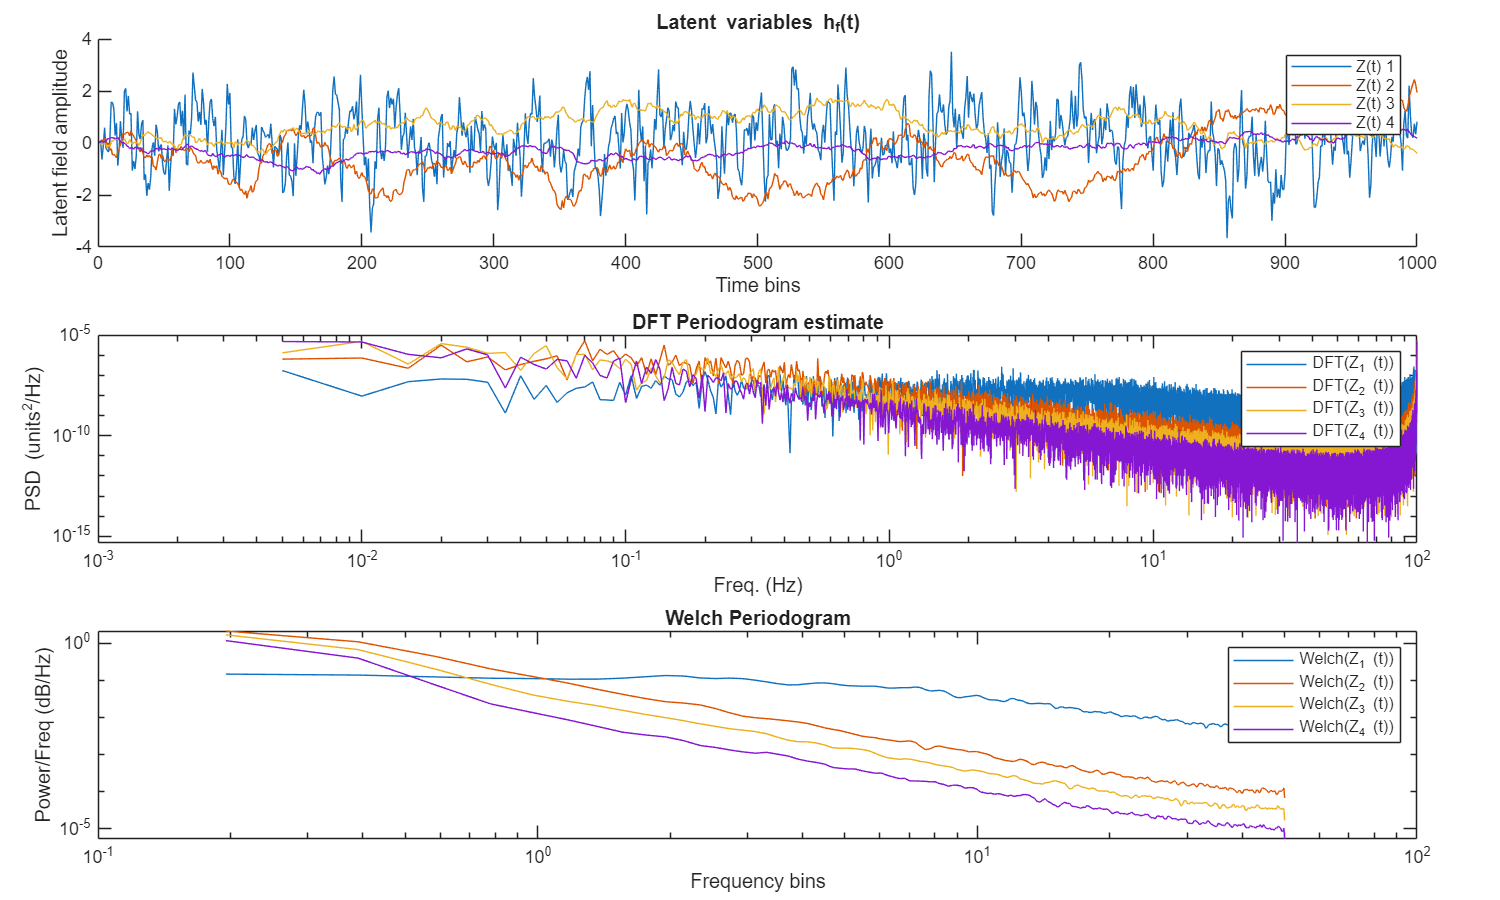

% DFT Periodogram Method
N = length(h_f);
H_F = fft(h_f); % DFT
fs = 1/param.dt;
H_F_dft_psd = (1/(N*fs) * abs(H_F)) .^2; % normalizing to get the PSD
freq_dft = (0:N-1) * (fs/N);

% Welch's Periodogram
window = hamming(256);
overlap = 128; % 50 % overlap
nfft = 512; % FFT length

[H_F_welch_psd, f_welch_psd] = pwelch(h_f, window,overlap,nfft,fs);

figure('Position',[50 50 1000 600])
tiledlayout(3, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
h_f_colors = lines(param.N_F);

nexttile
hold on;
for f=1:param.N_F
    plot(h_f(:, f), 'Color', h_f_colors(f, :),'DisplayName', ['Z(t) ' num2str(f)]);
end
xlabel('Time bins')
ylabel('Latent field amplitude')
title('Latent variables h_f(t)')
xlim([0 1000]);
legend( 'Show');
hold off;

nexttile
for f=1:param.N_F
    loglog(freq_dft, H_F_dft_psd(:,f),'Color',h_f_colors(f,:),'DisplayName',['DFT(Z_{' num2str(f) '} (t))']);
    hold on;
end
xlabel('Freq. (Hz)'); ylabel('PSD (units^2/Hz)');
title('DFT Periodogram estimate');
legend('show');
hold off;

nexttile
for f=1:param.N_F
    loglog(f_welch_psd, H_F_welch_psd(:,f),'Color',h_f_colors(f,:),'DisplayName',['Welch(Z_{' num2str(f) '} (t))']); % 
    hold on;
end
xlabel('Frequency bins')
ylabel('Power/Freq (dB/Hz)')
title('Welch Periodogram')
legend('show');
hold off;

- The DFT periodogram has a higher variance for each latent variable PSD compared to the Welch's method. The averaging over mangy segments has smoothed out the noise. 

-  The DFT's frequency resolution is fs/N= 100/20000= 0.005, while for Welch it is fs/L= 100/512= 0.20

- For stochastic signals and physiological signals Welch is a better method.

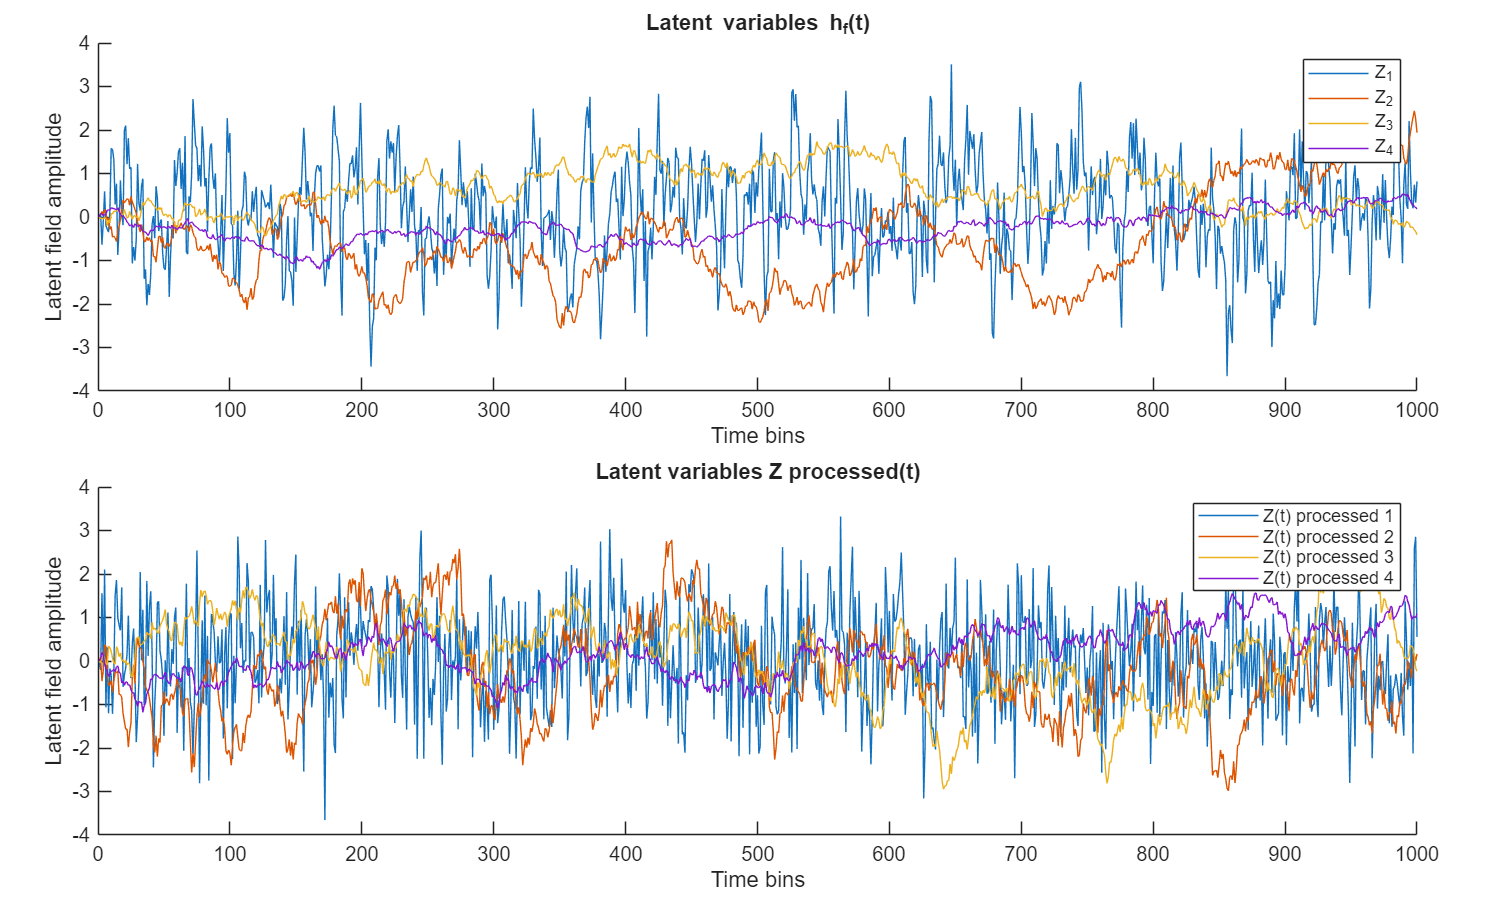

target_bin_size = 0.05; % 50 ms
tau = 25; % Post-synaptic kernel, Alpha kernel's number of bins to the peak of the kernel
smooth_sigma = 5; % Std. Dev. of the Gaussian kernel in bins
group_size = 8; % grouping of neurons per channel

[s_eeg_like, h_f_processed] = spike_to_eeg(s_i, h_f, param, target_bin_size, tau, group_size, smooth_sigma);

h_f_processed_psd = fft(h_f_processed);
h_f_processed_psd_mag = abs(h_f_processed_psd); % Compute the magnitude of the FFT

% TODO: - calculate the 1/f slope for each latent variable and compare with EEG PSD 1/f slope (h_f_welch_psd vs. eeg_welch_psd).

figure('Position',[50 50 1000 600])
tiledlayout(2, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
h_f_colors = lines(param.N_F);

nexttile
hold on;
for f=1:param.N_F
    plot(h_f(:, f), 'Color', h_f_colors(f, :),'DisplayName', ['Z_' num2str(f)]);
end
xlabel('Time bins')
ylabel('Latent field amplitude')
title('Latent variables h_f(t)')
xlim([0 1000]);
legend( 'Show');
hold off;

nexttile
hold on;
for f=1:param.N_F
    plot(h_f_processed(:, f), 'Color', h_f_colors(f, :),'DisplayName', ['Z(t) processed ' num2str(f)]);
end
xlabel('Time bins')
ylabel('Latent field amplitude')
title('Latent variables Z processed(t)')
xlim([0 1000]);
legend( 'Show');
hold off;

% 2. Manually build a minimal EEG structure
EEG = eeg_emptyset();
EEG.data   = s_eeg_like;
EEG.nbchan = size(EEG.data, 1);   % number of "channels" = neurons
EEG.pnts   = size(EEG.data, 2);   % number of time points
EEG.trials = 1;                   % continuous data
EEG.srate  = 100;                 % arbitrary sample rate (adjust if needed)
EEG.xmin   = 0;
EEG = eeg_checkset(EEG);

eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Plotting data using axis size [0.110714,0.116429]
limits: [xmin,xmax,ymin,ymax] = [ 0.0 399990.0 -5.35 5.35]
Plotting 1 traces of 40000 frames with colors: 'b' 
trace 1:  1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32
pop_plotdata(EEG, 1, [1:32] , [1:1], '', 0, 1, [0 0]);


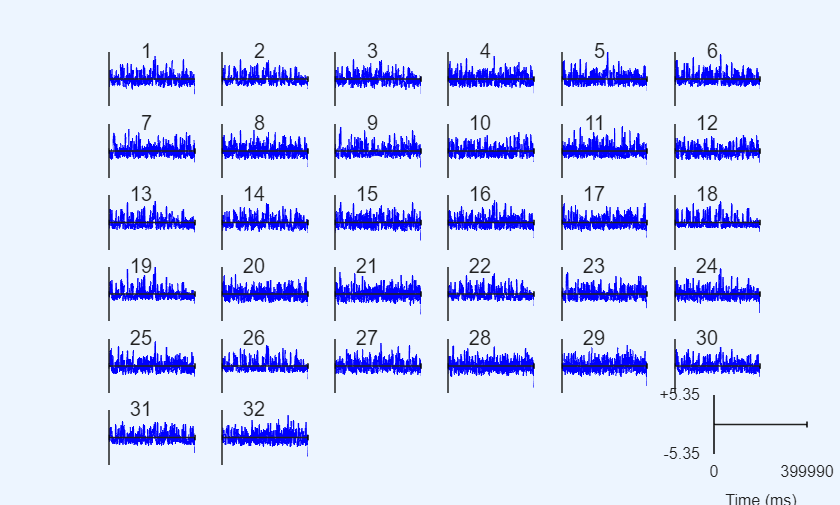

pop_plotdata(EEG,1, 1:32);

TODO: plot on the same axis and as nexttile next to laten variable

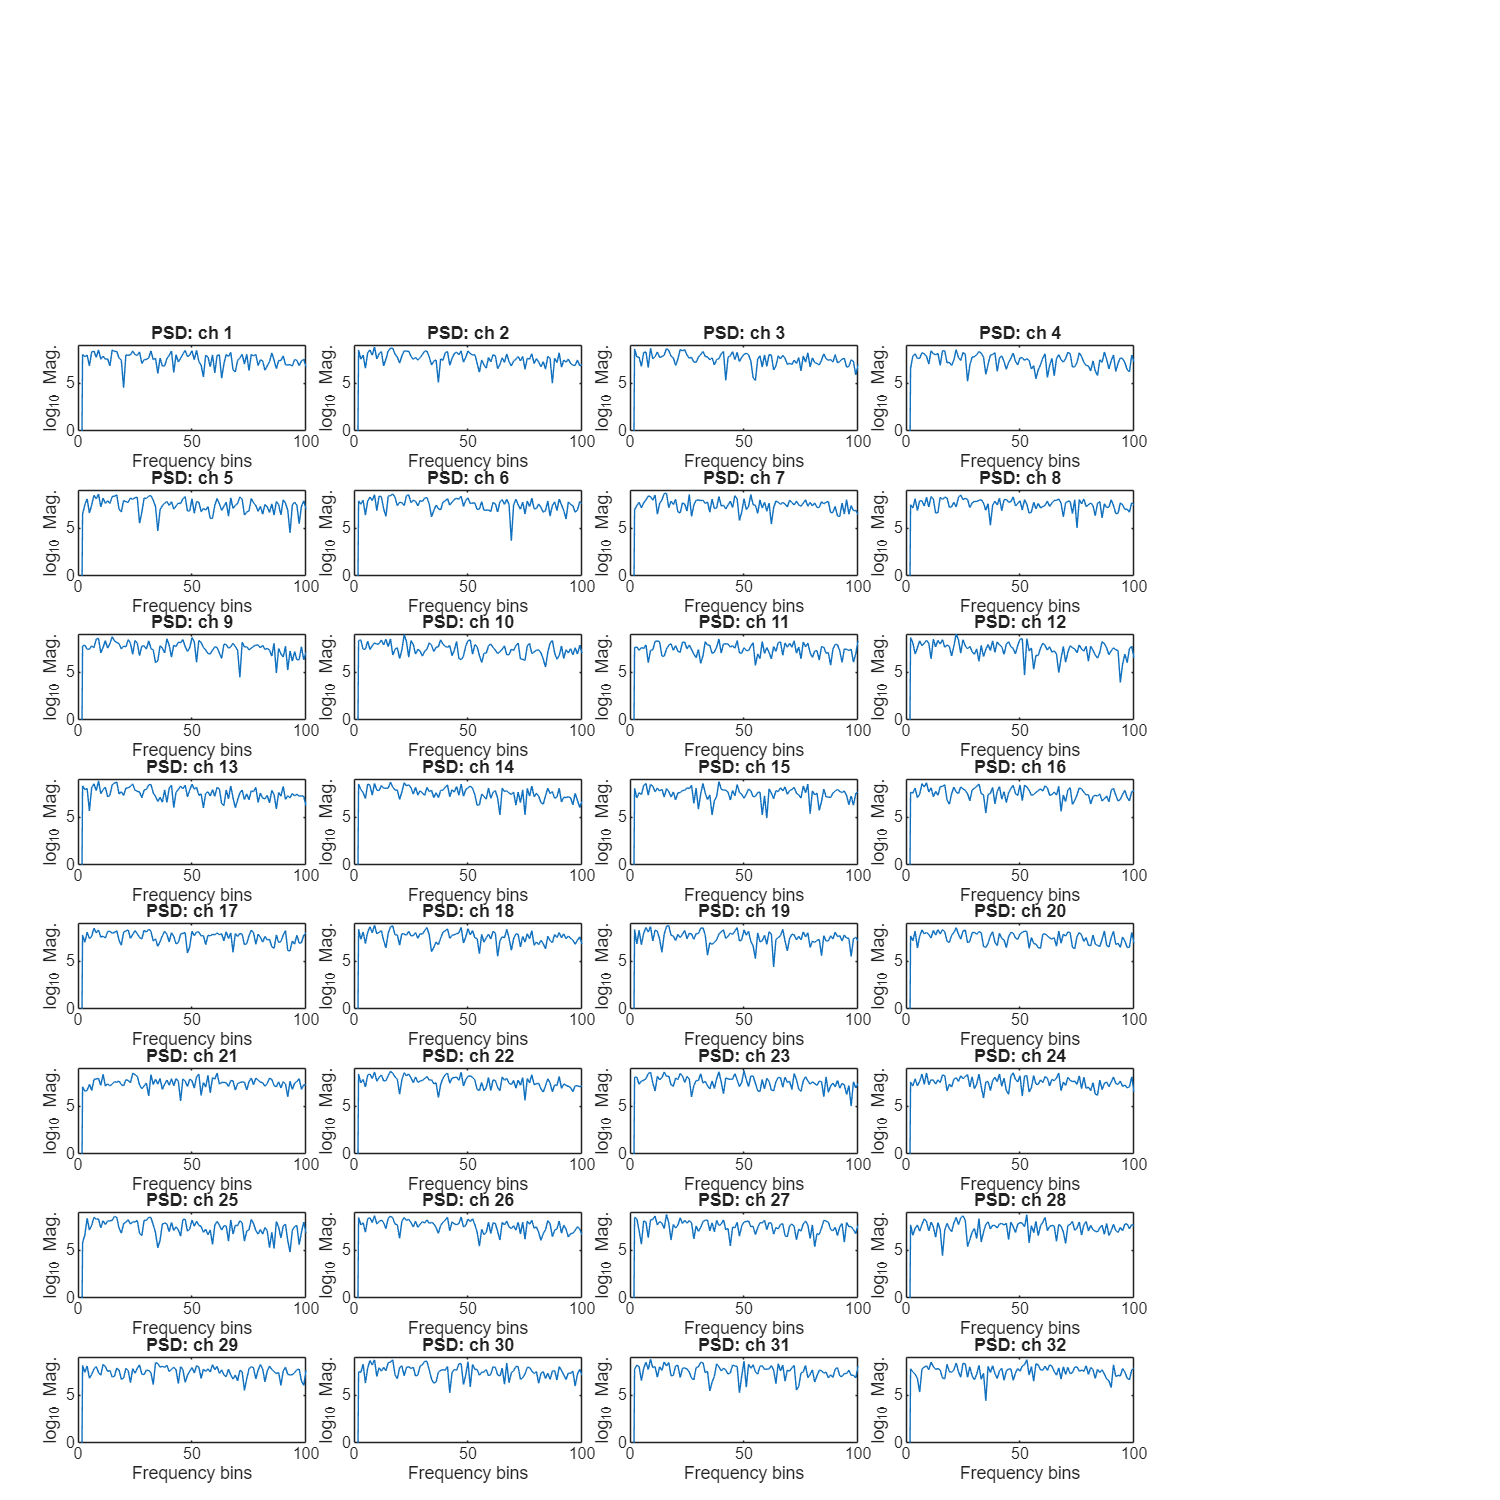

s_eeg_like_T = s_eeg_like';
eeg_psd = fft(s_eeg_like_T);
eeg_psd_mag = abs(eeg_psd); % Compute the magnitude of the FFT

%[psd, f_psd] = pwelch(s_eeg_like_T,param.T);

figure('Position',[50 50 1000 1000])
tiledlayout(8, 4, 'TileSpacing', 'compact', 'Padding', 'compact');


% nexttile
% plot(f_psd, log10(psd)) % log10(f_psd)
% xlabel('Frequency (Hz)') % log_{10} 
% ylabel('log_{10} Power spectral density')
% title('Log power spectrum of local readout')
for ch = 1:32
    nexttile
    plot(log(eeg_psd_mag(:, ch)));
    xlabel('Frequency bins')
    ylabel('log_{10} Mag.')
    title(['PSD: ch ', num2str(ch)] )
    xlim([0 100]);
    ylim([0 9]);
end

- **Looking at the magnitude of the signals in frequency domain, 0- ~50 Hz frequecy components of Z (t) are reflected in X(t). On the other hand, the frequencies greater than 50 Hz are not reflected well and have a very small magnitude.**

- Furthermore, there is a decrease in magnitute in the frequencies of X(t) comprared to relative constant magnitude in Z(t). On the other hand, the latent variables in Z(t) dont' have such decrease, and when they do, it's small. 

## 2. Dimensionality Reduction Methods

**Why? **

              Examine *overall*accuracy metrics and check against visualization of reconstructed trajectories. 

**Select at least:**

- Two **linear methods** (e.g., PCA or ICA)

- Two **nonlinear methods** (e.g., UMAP, neural network, t-SNE)

**Tasks for each method:**

- Reconstruct from .

- Report:

- Total   between   and  

- 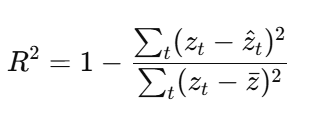

- Visual comparison of trajectories

% Marchenko–Pastur threshold
eig_vals = eig(cov(s_eeg_like'));
[N, T] = size(s_eeg_like);
Q = T / N;
sigma2 = mean(eig_vals);           % crude estimate of noise variance
lambda_max = sigma2 * (1 + sqrt(1/Q))^2;

% Find number of components above the MP threshold
num_sig_components = sum(eig_vals > lambda_max);
fprintf('Marchenko–Pastur suggests keeping %d PCs\n', num_sig_components);

Marchenko–Pastur suggests keeping 4 PCs



% [s_i_test, param_test, h_f_test] = sampleMorrellModel(param);
% [s_eeg_like_test, h_f_processed_test] = spike_to_eeg(s_i_test,h_f_test, param, target_bin_size,tau, group_size, smooth_sigma);

### **The two linear methods: PCA, ICA**

- For the reconstruction error: divide by var per latent variable before calculating R^2

-  For orerall accuracies, also show the PC trace over the period

- also calcualte various timem delays vs. R^2

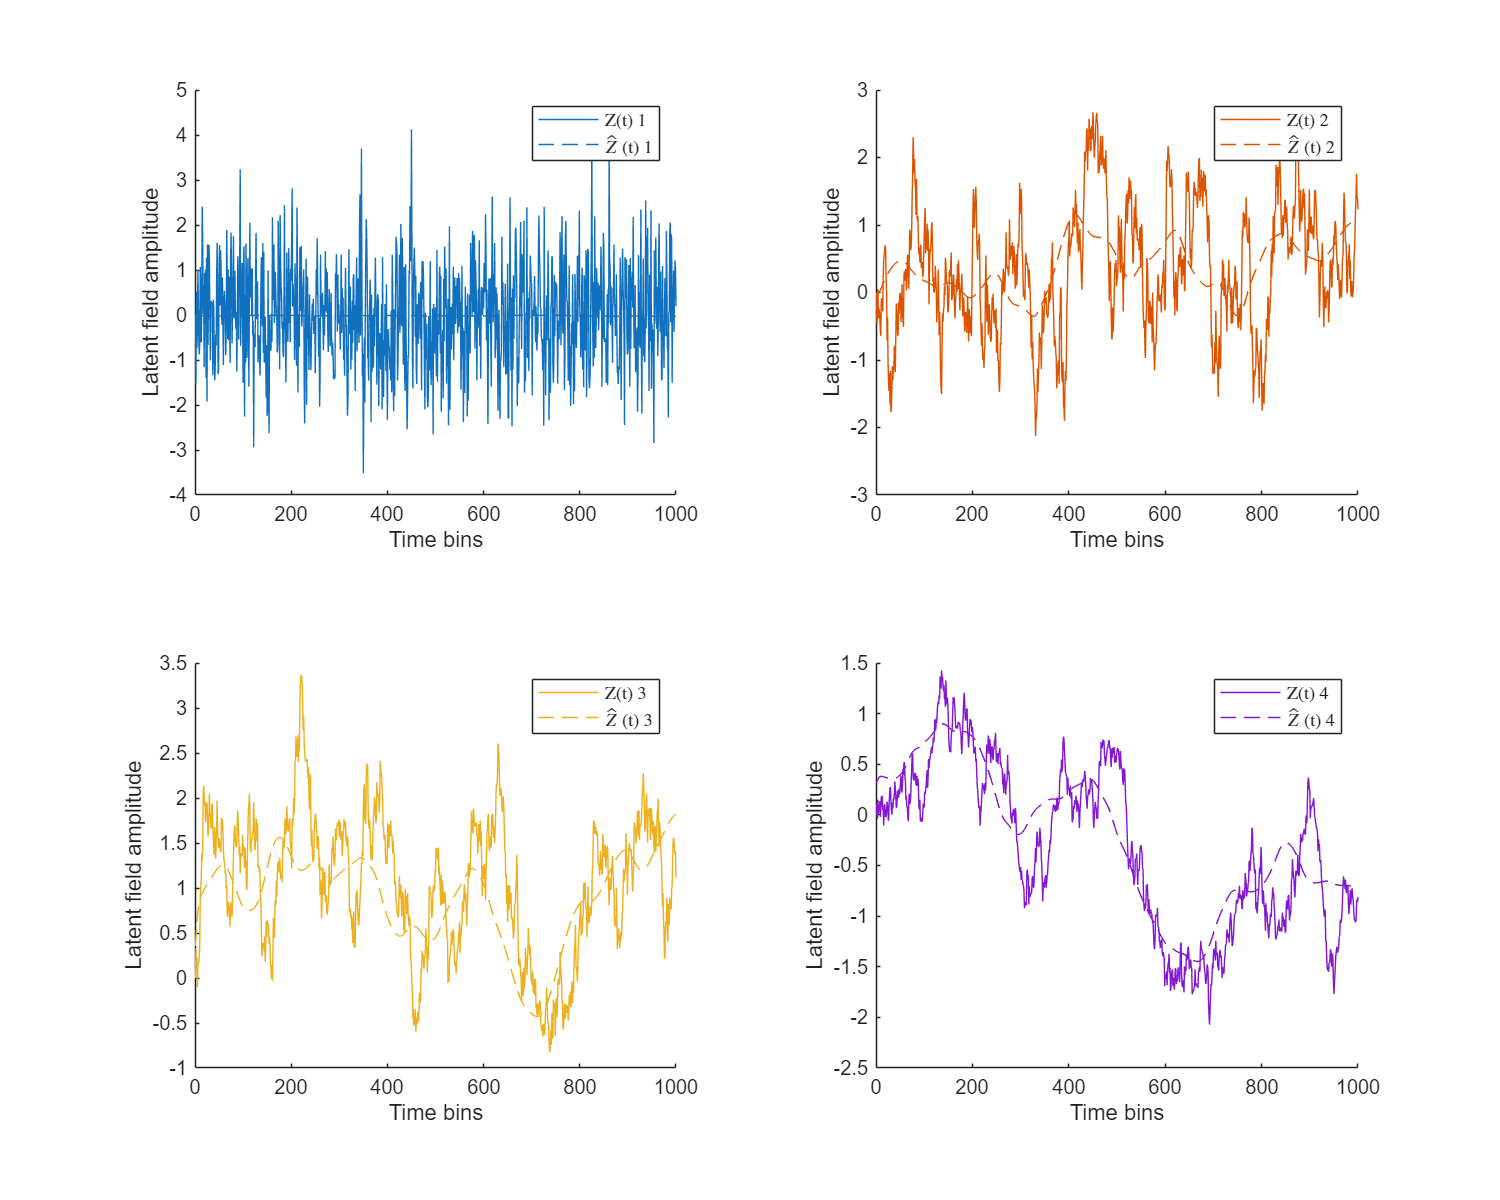


% 1. PCA Analysis
% Run PCA on training data
[coeff, score, ~, ~, explained] = pca(s_eeg_like');
% For the reconstruction error: divide by var per latent variable before
% calculating R^2
% For overall accuracies, also show the PC trace over the period
% also calcualte various time delays vs. R^2

h_f_recon = zeros(size(h_f_processed));
reconstruction_error_pca = zeros(num_sig_components, param.N_F);

for idx = 1:num_sig_components
    for f = 1:param.N_F
        % Train
        w = lsqlin(score(:,1:idx), h_f_processed(:,f));
        h_f_recon(:,f) = score(:,1:idx) * w;
        % reconstruction_error_pca(idx, f) = mean((h_f(:,f) - h_f_recon_train).^2);
        numerator = sum((h_f_processed(:,f) - h_f_recon(:,f)).^2);
        denominator = sum((h_f_processed(:,f) - mean(h_f_processed(:,f))).^2);
        reconstruction_error_pca(idx, f) = 1 - (numerator / denominator);

    end
    s_eeg_reconstructed = score(:,1:idx) * coeff(:,1:idx)';

end
% R 
figure('Position',[50 50 1000 800])
tiledlayout(4, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
h_f_colors = lines(param.N_F);
title('Latent variables Z(t) and $\hat{z}(t)$', 'Interpreter', 'latex')

for f=1:param.N_F
    nexttile
    hold on;
    plot(h_f_processed(:, f),'LineStyle', '-', 'Color', h_f_colors(f, :),'DisplayName', ['Z(t) ' num2str(f)]);
    plot(h_f_recon(:, f), 'LineStyle', '--','Color', h_f_colors(f, :),'DisplayName', ['$\hat{Z}$ (t) ' num2str(f)]);
    xlabel('Time bins')
    ylabel('Latent field amplitude')
    xlim([0 1000]);
    legend('Show','Interpreter', 'latex');
    hold off;
end

- **Visual Comparison of the Z(t) with **$\hat{Z} \left(t\right)$: The reconstruction is missing the high frequency activity.

figure('Position',[50 50 800 600])
tiledlayout(2, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
nexttile
plot(cumsum(explained), 'o-');
xlabel('Number of PCs');
ylabel('Cumulative Variance Explained (%)');
title('PCA Explained Variance');

nexttile
for f = 1:param.N_F
    hold on;
    plot(reconstruction_error_pca(:,f),'Marker', 'o','Color',h_f_colors(f,:),'DisplayName', ['R^2 ' num2str(f)]);
    
end
% Adding axis labels and title
xlabel('Feature Index'); % X-axis label
ylabel('R² Value');      % Y-axis label
title('PCA R² Values for Different Features'); % Title
hold off;
legend('show');

- Increase in R^2 for latent 4, 3, and 2 close to 1, shows improved reconstruction. For Latent 1 the improvement is much smaller starting from PC 3 to 4 and 5, and latent 4 has the best reconstruction. For Latent 4 gets to 0.8 by PC 4 closest to 1.

% Run ICA with PCA whitening to num_comps
EEG = pop_runica(EEG, 'extended',1, 'pca', num_sig_components, 'interrupt','off');


         is not modeling the entire data, only the PCA-reduced data.
Attempting to convert data matrix to double precision for more accurate ICA results.

Input data size [4,40000] = 4 channels, 40000 frames/nAfter PCA dimension reduction,
  finding 4 ICA components using extended ICA.
Kurtosis will be calculated initially every 1 blocks using 6000 data points.
Decomposing 2500 frames per ICA weight ((16)^2 = 40000 weights, Initial learning rate will be 0.001, block size 53.
Learning rate will be multiplied by 0.98 whenever angledelta >= 60 deg.
More than 32 channels: default stopping weight change 1E-7
Training will end when wchange < 1e-06 or after 512 steps.
Online bias adjustment will be used.
Removing mean of each channel ...
Final training data range: -4.27286 to 5.34724
Reducing the data to 4 principal dimensions...
Computing the sphering matrix...
Starting weights are the identity matrix ...
Sphering the data ...
Begin

icasig = double(EEG.icaact)';  % time × ICs

% Reconstruction error per latent on train & test
reconstruction_error_ica = zeros(num_sig_components, param.N_F); 
h_f_reconstructed_ica = zeros(size(h_f_processed));

for idx = 1:num_sig_components
    for f = 1:param.N_F
        % fit on train
       % Reconstruct latent field f from first 'idx' ICs using least-squares
        x = lsqlin(icasig(:,1:idx), h_f_processed(:,f));
        h_f_reconstructed_ica(:,f) = icasig(:,1:idx) * x;
        % rec_err(idx,f) = mean((h_f(:,f) - h_f_reconstructed_ica).^2);
        numerator = sum((h_f_processed(:,f) - h_f_reconstructed_ica(:,f)).^2);
        denominator = sum((h_f_processed(:,f) - mean(h_f_processed(:,f))).^2);
        reconstruction_error_ica(idx, f) = 1 - (numerator / denominator);

    end
end
figure('Position',[50 50 1000 800])
tiledlayout(4, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
h_f_colors = lines(param.N_F);
title('ICA Latent variables Z(t) and $\hat{z}(t)$', 'Interpreter', 'latex')

for f=1:param.N_F
    nexttile
    hold on;
    plot(h_f_processed(:, f),'LineStyle', '-', 'Color', h_f_colors(f, :),'DisplayName', ['Z(t) ' num2str(f)]);
    plot(h_f_reconstructed_ica(:, f), 'LineStyle', '--','Color', h_f_colors(f, :),'DisplayName', ['$\hat{Z}$ (t) ' num2str(f)]);
    xlabel('Time bins')
    ylabel('Latent field amplitude')
    xlim([0 1000]);
    legend('Show','Interpreter', 'latex');
    hold off;
end

- **Visual Comparison of the Z(t) with **$\hat{Z} \left(t\right)$: The reconstruction is missing the high frequency activity and the peak and throughs don't match perfectly.

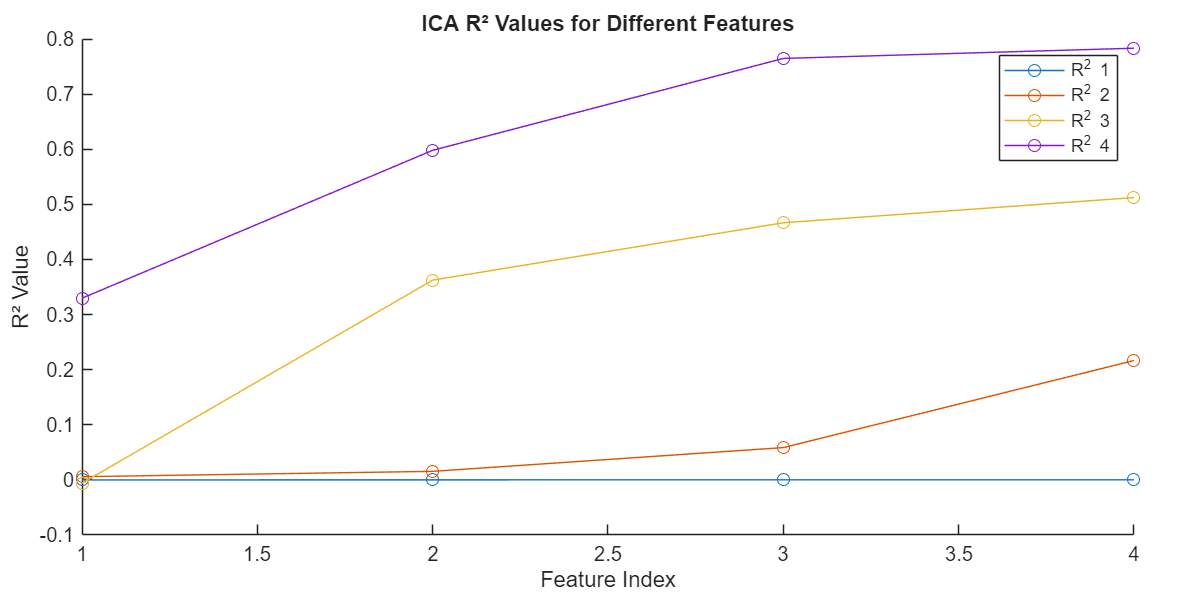

figure('Position',[50 50 800 400])
tiledlayout(1, 1, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile
for f = 1:param.N_F
    hold on;
    plot(reconstruction_error_ica(:,f),'Marker', 'o','Color',h_f_colors(f,:),'DisplayName', ['R^2 ' num2str(f)]);
    
end
% Adding axis labels and title
xlabel('Feature Index'); % X-axis label
ylabel('R² Value');      % Y-axis label
title('ICA R² Values for Different Features'); % Title
hold off;
legend('show');

- Similar results to PCA: Increase in R^2 for latent 4, 3, and 2 close to 1, shows improved reconstruction. For Latent 4 gets to 0.8 by PC 3 closest to 1, while latent 1,2 and 3 keep improving after PC 3 to 5.

### Two Non-linear methods: UMAP and t-SNE

% UMAP

n_neighbors = 18;
min_dist    = 0.10;

[umap_s_i, ~] = run_umap(s_eeg_like_T, 'n_neighbors', n_neighbors, 'min_dist', min_dist, ...
    'n_components', num_sig_components, 'verbose', 'none', 'gui', false);


cluster_idx = kmeans(h_f_processed, param.N_F);  % cluster based on true latent dynamics

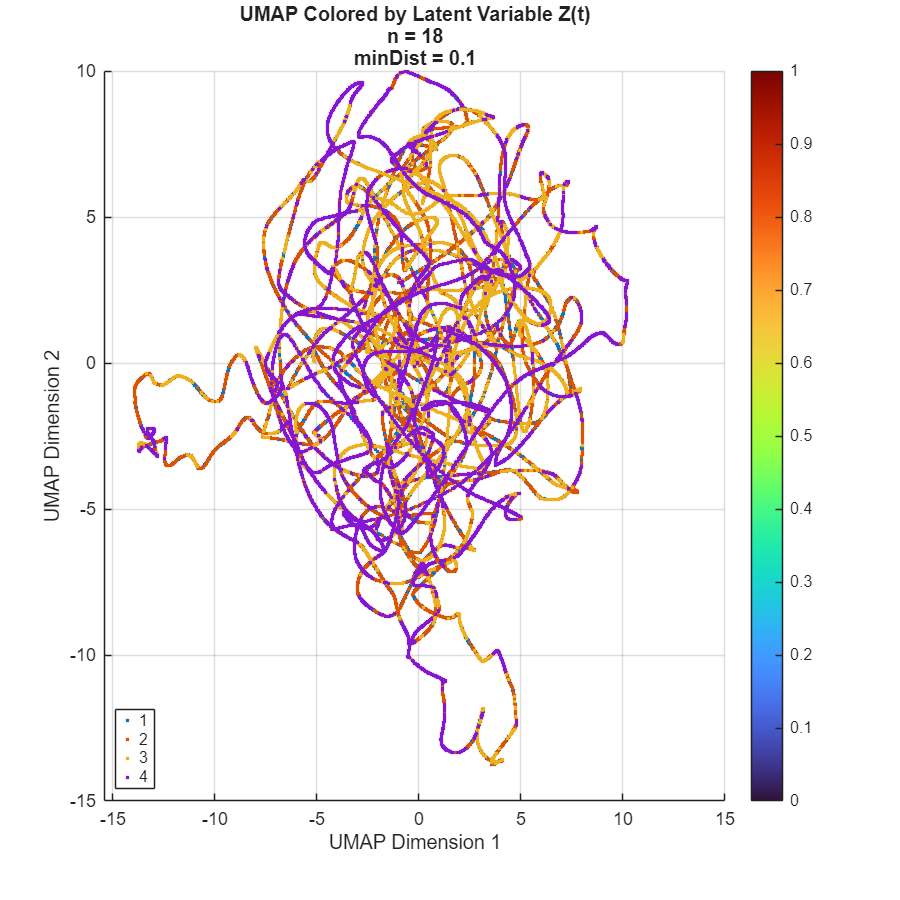


figure('Position', [100, 100, 600, 600]);
gscatter(umap_s_i(:,1), umap_s_i(:,2), cluster_idx);
xlabel('UMAP Dimension 1');
ylabel('UMAP Dimension 2');
title({['UMAP Colored by Latent Variable Z(t)'], ...
       ['n = ' num2str(n_neighbors)], ...
       ['minDist = ' num2str(min_dist)]});
colormap turbo;
colorbar; grid on;

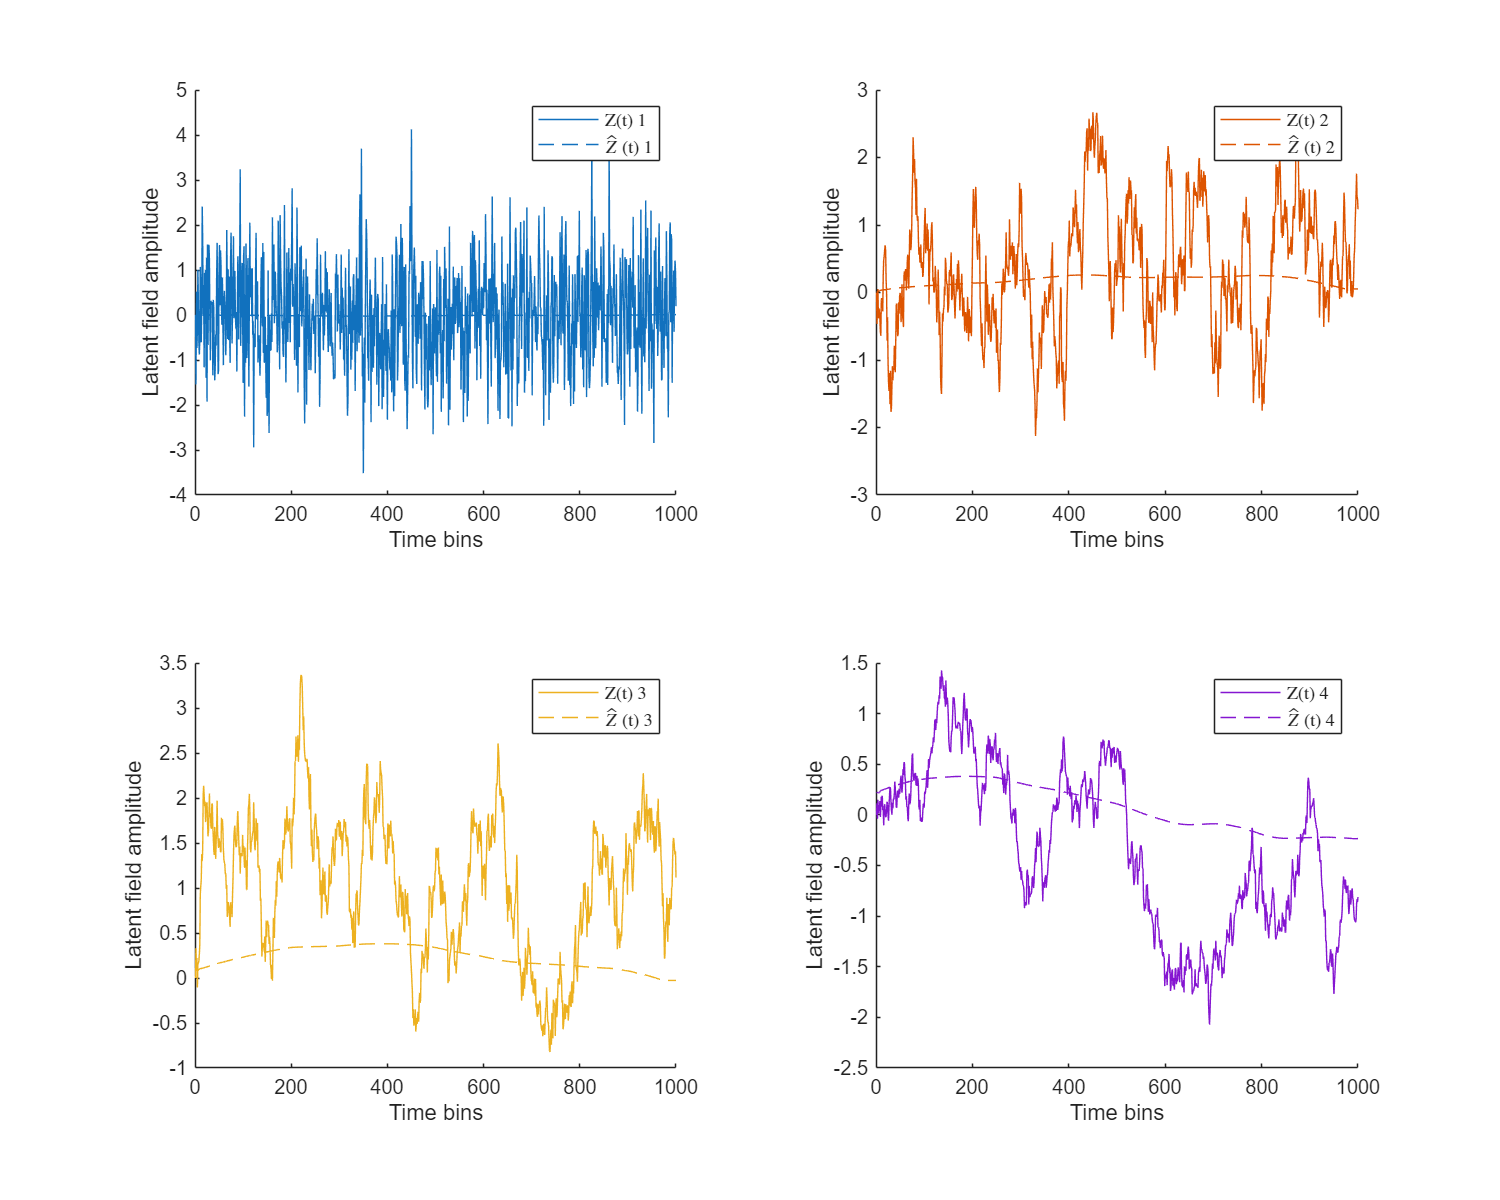

reconstruction_error_umap = zeros(num_sig_components, param.N_F);
h_f_reconstructed_umap = zeros(size(h_f_processed));

for idx = 1:num_sig_components
    for f = 1:param.N_F
        % Reconstruct latent field f from first 'idx' UDs using least-squares
        x_umap = lsqlin(umap_s_i(:, 1:idx), h_f_processed(:,f));
        h_f_reconstructed_umap(:,f) = umap_s_i(:, 1:idx) * x_umap;
        % reconstruction_error_umap(idx,f) = mean((h_f_processed(:,f) - h_f_reconstructed_umap).^2);
        numerator = sum((h_f_processed(:,f) - h_f_reconstructed_umap(:,f)).^2);
        denominator = sum((h_f_processed(:,f) - mean(h_f_processed(:,f))).^2);
        reconstruction_error_umap(idx, f) = 1 - (numerator / denominator);
    end
end

figure('Position',[50 50 1000 800])
tiledlayout(4, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
h_f_colors = lines(param.N_F);
title('UMAP Latent variables Z(t) and $\hat{z}(t)$', 'Interpreter', 'latex')

for f=1:param.N_F
    nexttile
    hold on;
    plot(h_f_processed(:, f),'LineStyle', '-', 'Color', h_f_colors(f, :),'DisplayName', ['Z(t) ' num2str(f)]);
    plot(h_f_reconstructed_umap(:, f), 'LineStyle', '--','Color', h_f_colors(f, :),'DisplayName', ['$\hat{Z}$ (t) ' num2str(f)]);
    xlabel('Time bins')
    ylabel('Latent field amplitude')
    xlim([0 1000]);
    legend('Show','Interpreter', 'latex');
    hold off;
end

- The Z hat looks worser for UMAP, than PCA or ICA. It is lacking spatial resolution. 

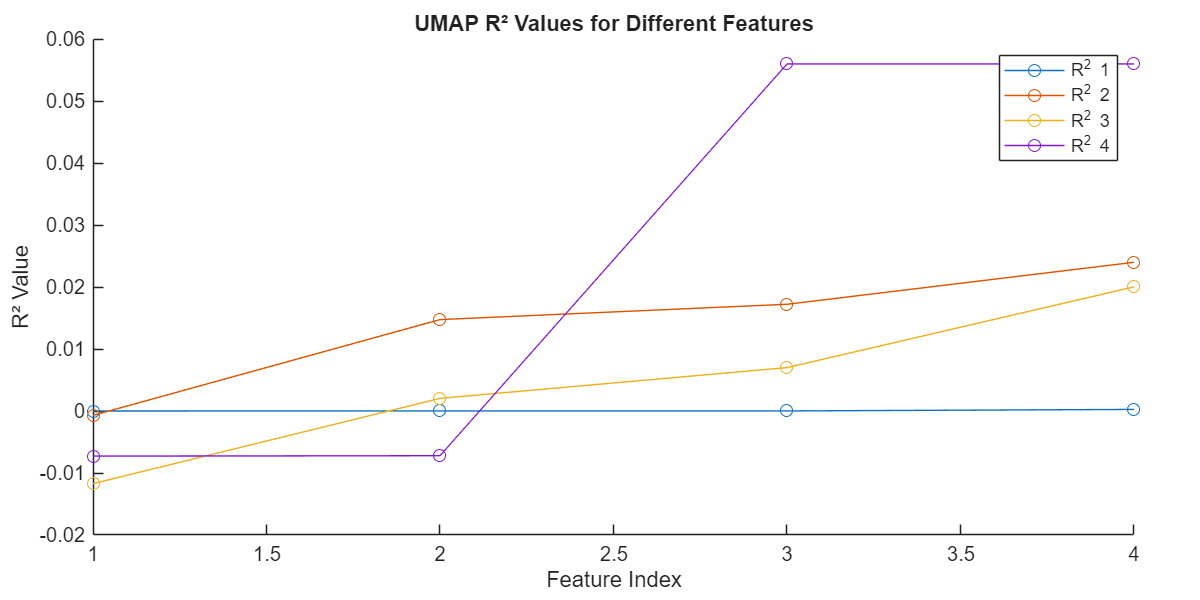

figure('Position',[50 50 800 400])
tiledlayout(1, 1, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile
for f = 1:param.N_F
    hold on;
    plot(reconstruction_error_umap(:,f),'Marker', 'o','Color',h_f_colors(f,:),'DisplayName', ['R^2 ' num2str(f)]);
    
end
% Adding axis labels and title
xlabel('Feature Index'); % X-axis label
ylabel('R² Value');      % Y-axis label
title('UMAP R² Values for Different Features'); % Title
hold off;
legend('show');

- Latent 4 has the best R^2 after PC2 and gets to 0.5 by PC5. Small increase in R^2 for latent 3, and for Latent 1 that is equal to zero, it means that the reconstruction is not bettern than mean. Latent 2 has a bigger improvement from PC3 to 4. 

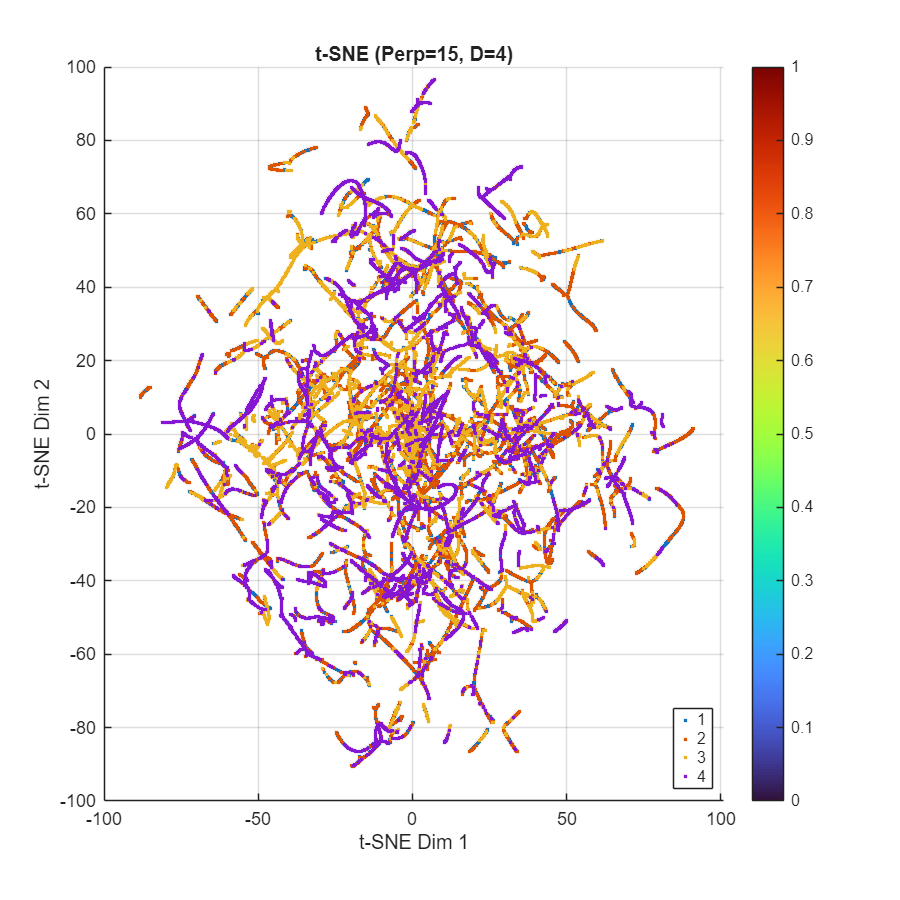

% t-SNE
perplexity = 15;
num_dims = num_sig_components;
tsne_s_i = tsne(s_eeg_like_T, 'Perplexity', perplexity, 'NumDimensions', num_dims, ...
    'NumPCAComponents',   num_sig_components);

figure('Position',[100,100,600,600]);
gscatter(tsne_s_i(:,1), tsne_s_i(:,2), cluster_idx);
xlabel('t-SNE Dim 1');
ylabel('t-SNE Dim 2');
title(sprintf('t-SNE (Perp=%d, D=%d)', perplexity, num_dims));
colormap turbo; colorbar; grid on;

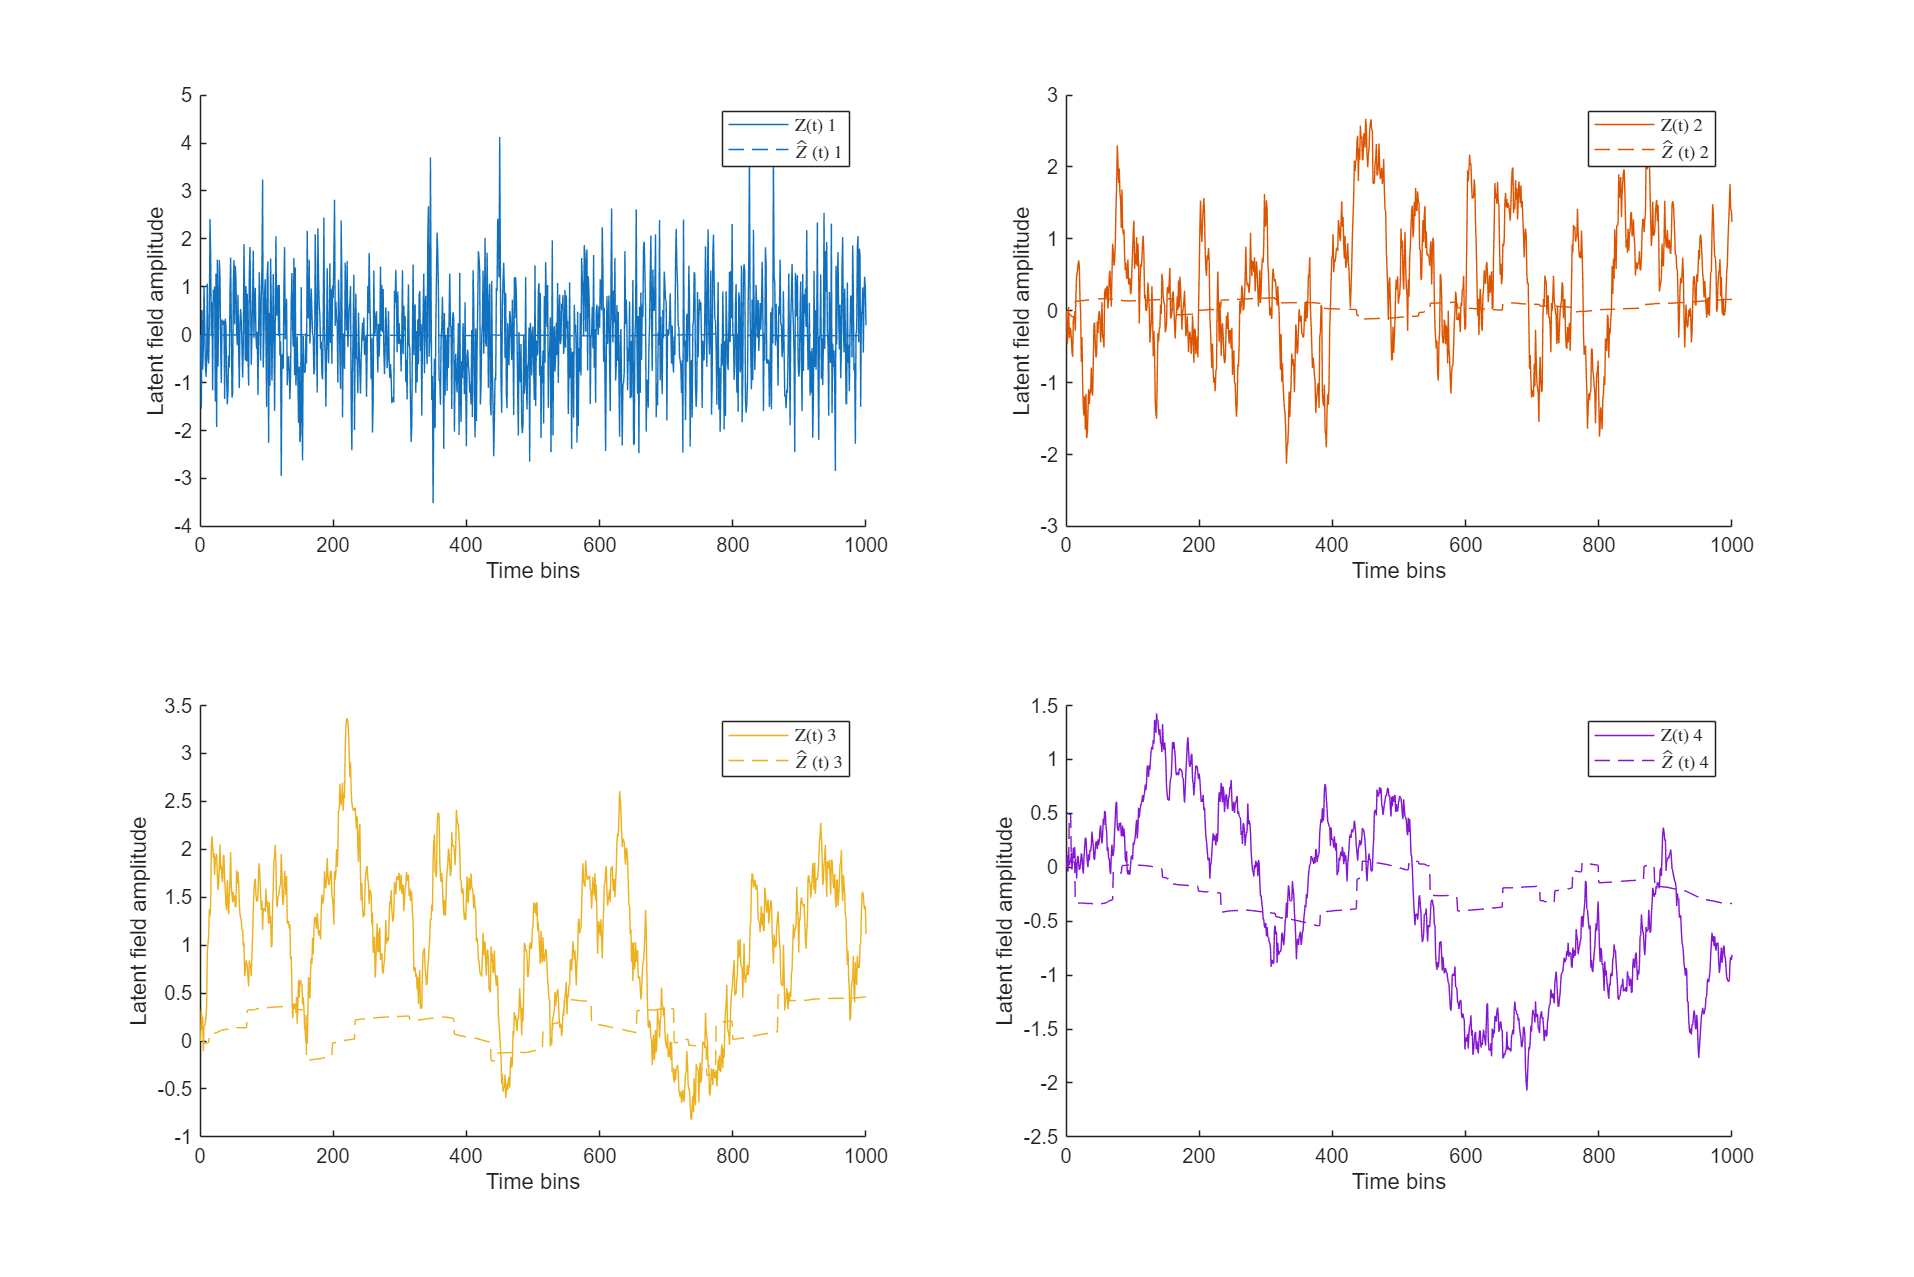

reconstruction_error_tsne = zeros(num_sig_components, param.N_F);
h_f_reconstructed_tsne = zeros(size(h_f_processed));

for idx = 1:num_sig_components
    for f = 1:param.N_F
        % Reconstruct latent field f from first 'idx' UDs using least-squares
        x_tsne = lsqlin(tsne_s_i(:, 1:idx), h_f_processed(:,f));
        h_f_reconstructed_tsne(:,f) = tsne_s_i(:, 1:idx) * x_tsne;
        % reconstruction_error_umap(idx,f) = mean((h_f_processed(:,f) - h_f_reconstructed_umap).^2);
        numerator = sum((h_f_processed(:,f) - h_f_reconstructed_tsne(:,f)).^2);
        denominator = sum((h_f_processed(:,f) - mean(h_f_processed(:,f))).^2);
        reconstruction_error_tsne(idx, f) = 1 - (numerator / denominator);
    end
end

figure('Position',[50 50 1500 1000])
tiledlayout(4, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
h_f_colors = lines(param.N_F);
title('t-SNE Latent variables Z(t) and $\hat{z}(t)$', 'Interpreter', 'latex')

for f=1:param.N_F
    nexttile
    hold on;
    plot(h_f_processed(:, f),'LineStyle', '-', 'Color', h_f_colors(f, :),'DisplayName', ['Z(t) ' num2str(f)]);
    plot(h_f_reconstructed_tsne(:, f), 'LineStyle', '--','Color', h_f_colors(f, :),'DisplayName', ['$\hat{Z}$ (t) ' num2str(f)]);
    xlabel('Time bins')
    ylabel('Latent field amplitude')
    xlim([0 1000]);
    legend('Show','Interpreter', 'latex');
    hold off;
end

- The Z hat for t-SNE looks better than UMAP. But still has medium frequency components as in ICA and PCA. 

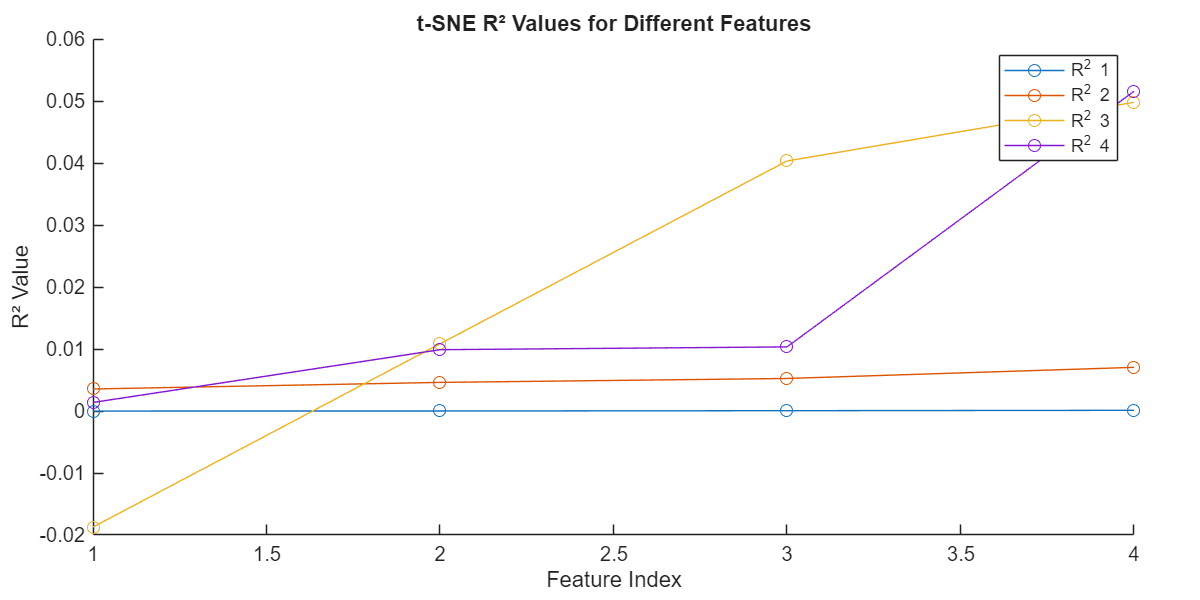

figure('Position',[50 50 800 400])
tiledlayout(1, 1, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile
for f = 1:param.N_F
    hold on;
    plot(reconstruction_error_tsne(:,f),'Marker', 'o','Color',h_f_colors(f,:),'DisplayName', ['R^2 ' num2str(f)]);
    
end
% Adding axis labels and title
xlabel('Feature Index'); % X-axis label
ylabel('R² Value');      % Y-axis label
title('t-SNE R² Values for Different Features'); % Title
hold off;
legend('show');

Latent 4 has the best R^2 after PC2 and gets to 0.6 by PC5. Small increase in R^2 for latent 2 and for Latent 1 that is equal to zero, it means that the reconstruction is not bettern than mean. Latent 2 has small improvments till PC 3. 

## 3. Frequency‑Resolved Analysis

**Why? **

              The latent variables may have different frequency content than the EEG signal. We want to know the limits of reconstruction and signatures of failure. A. CPSD / Spectral R2(f)R^2(f)

- Compute Fourier transforms .

- For each dimension:

- Plot  across frequencies (for each latent dimension). Recommended to divide long time series into shorter “trials” (~3 seconds each) and average over these. 

B. Multitaper Coherence

- Estimate coherence using multitaper methods (include 95% confidence intervals). Use Chronux (http://chronux.org)

- Identify frequency bands where coherence drops below statistical significance.

- Compare these bands across different reconstruction methods.